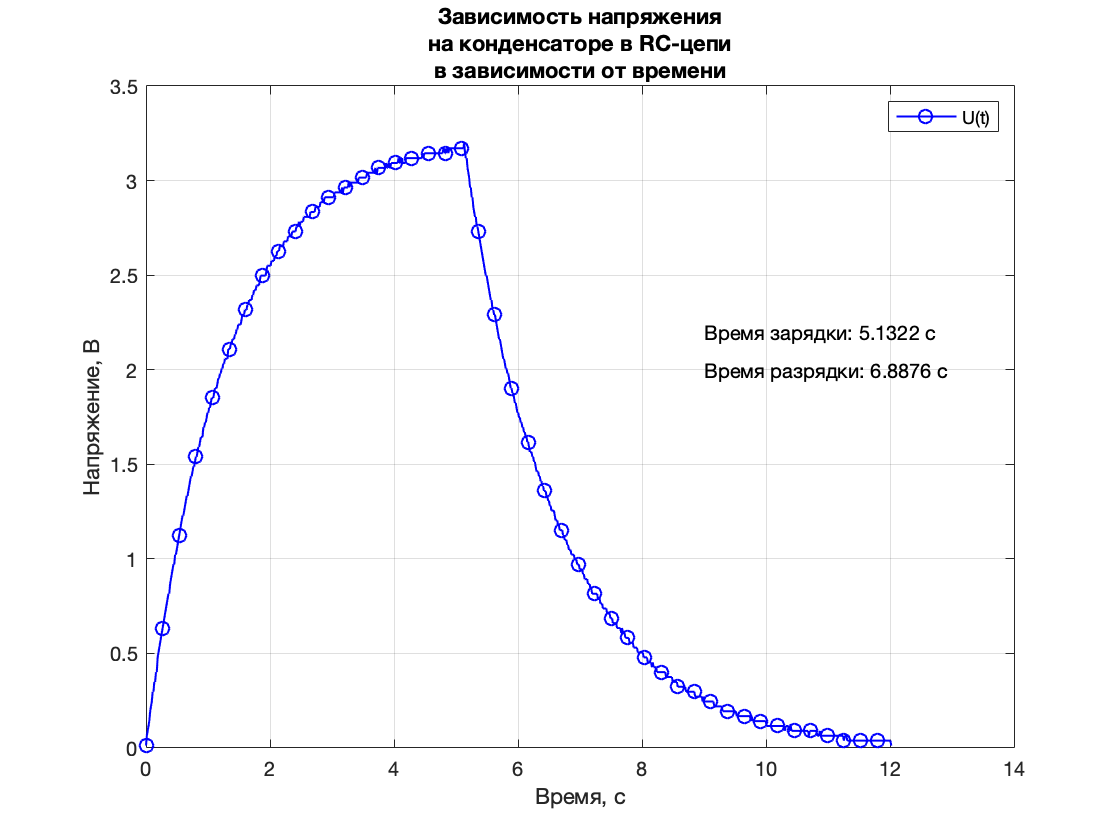

voltage = importdata('/Users/karimvafin/Documents/MATLAB/Общеинженерная подготовка/data.txt')';
settings = importdata('/Users/karimvafin/Documents/MATLAB/Общеинженерная подготовка/settings.txt')';
dt = settings(1);
voltage = voltage*3.3/255;
timeEnd = (length(voltage)-1)*dt;
time = linspace(0,timeEnd,length(voltage));
f = figure("Name","Вафин Карим, Б03-006","NumberTitle","off");
figure(f);
plot(time,voltage,"b-o","LineWidth",1,"MarkerIndices",1:20:length(time),"MarkerSize",7);
grid on;
title({'Зависимость напряжения';'на конденсаторе в RC-цепи';'в зависимости от времени'});
ylabel("Напряжение, В");
xlabel("Время, с");
legend("U(t)");
[Vmax,ind]=max(voltage);
tmax = time(ind);
tup = tmax;
tdown = timeEnd-tmax;
str1 = ['Время зарядки: ',num2str(tup),' c'];
str2 = ['Время разрядки: ',num2str(tdown),' c'];
text(9,2.2,str1);
text(9,2,str2);
saveas(f,"U(t)modified.png");